## Run Files

% Run files
DataLoading();
Pitot_Airspeed();
Venturi_Airspeed();
Water_Airspeed();

## Clean Up

clear all;
clc;

## Equations

% Pitot-Static Probe Configuration
% Takes in deltaP, R, Tatm, Patm
% Outputs velocity (need to check units)
PitotStaticProbeConfig = @(deltaP, R, Tatm, Patm) sqrt(2 * deltaP * ((R * Tatm) / Patm));

% Venturi Tube Configuration
% Takes in deltaP, R, Tatm, Patm, A1, A2
% Outputs velocity (need to check units)
VenturiTubeConfig = @(deltaP, R, Tatm, Patm, A1, A2) sqrt((2 * deltaP * R * Tatm) / (Patm * (1 - (A2/A1)^2)));

% Bernoulli's Equation
% Takes in ideal gas constant, atm temp/pressure, change in pressure in wind tunnel
% Outputs airspeed
BernoulliEq = @(deltaP,Tatm,Patm,R) sqrt(2*deltaP*((R*Tatm)/Patm));

% Coefficient of pressure
% Takes in V_local, V_inf
C_P = @(V_local,V_inf) 1 - ((V_local^2)/(V_inf^2));

% Coefficient of drag
% Takes in L,q_inf,S
C_L =@(L,q_inf,S) L/(q_inf*S);

% Coefficient of lift
% Takes in D,q_inf,S
C_D = @(D,q_inf,S) D/(q_inf*S);

% Reference Area
% Takes in c,b
S = @(c,b) c*b;

## Load Data

% Load airspeed and voltage data from pitot and venturi calculations
load('VenturiAirspeedData.mat');
load('PitotAirspeedData.mat');
load('WaterAirspeedData.mat');

## Section 5

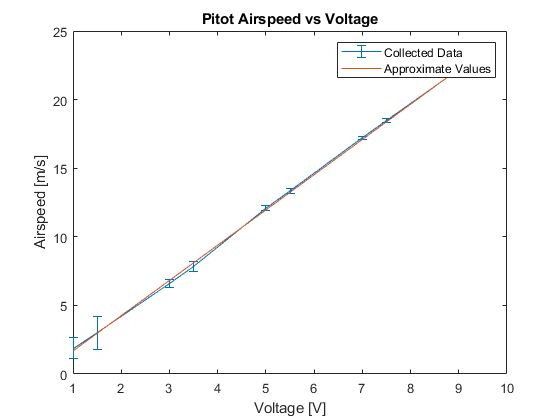

% Curve fit for each airspeed - voltage data
[polyVentAir, errorPolyVentAir] = polyfit(VoltageVenturi, AirspeedVenturi, 1);
[polyPitotAir, errorPolyPitotAir] = polyfit(VoltagePitot, AirspeedPitot, 1);
[polyVentWater, errorPolyVentWater] = polyfit(finalAvg.Voltage, finalAvg.AirspeedV, 1);
[polyPitotWater, errorPolyPitotWater] = polyfit(finalAvg.Voltage, finalAvg.AirspeedP, 1);

% Find fitted values
[PitotAir, deltaPitotAir] = polyval(polyPitotAir, VoltagePitot, errorPolyPitotAir);
[VenturiAir, deltaVenturiAir] = polyval(polyVentAir, VoltageVenturi, errorPolyVentAir);
[PitotWater, deltaPitotWater] = polyval(polyPitotWater, finalAvg.Voltage, errorPolyPitotWater);
[VenturiWater, deltaVenturiWater] = polyval(polyVentWater, finalAvg.Voltage, errorPolyVentWater);

% Plot Pitot Tube Airspeed Data
errorbar(VoltagePitot, AirspeedPitot, EPitotAir);
hold on;
plot(VoltagePitot, PitotAir);
hold off;
xlabel('Voltage [V]');
ylabel('Airspeed [m/s]');
title('Pitot Airspeed vs Voltage');
legend('Collected Data', 'Approximate Values');

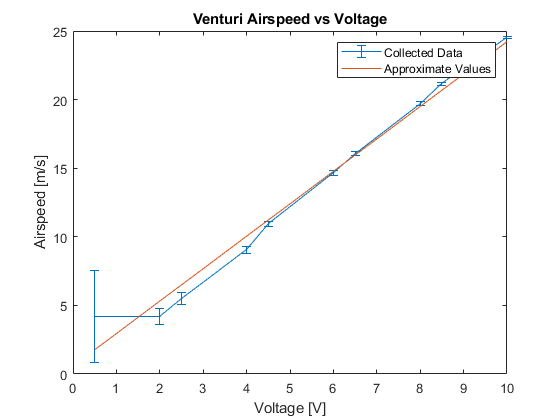


% Plot Venturi Airspeed Data
errorbar(VoltageVenturi, AirspeedVenturi, EVenturiAir);
hold on;
plot(VoltageVenturi, VenturiAir);
hold off;
xlabel('Voltage [V]');
ylabel('Airspeed [m/s]');
title('Venturi Airspeed vs Voltage');
legend('Collected Data', 'Approximate Values');

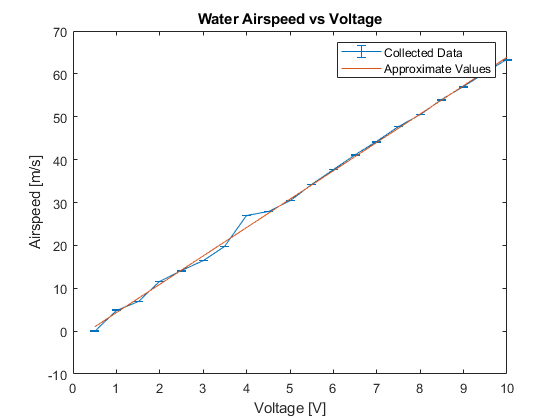


% Plot Water Airspeed Data
errorbar(finalAvg.Voltage, finalAvg.AirspeedP, EPitotWater);
hold on;
plot(finalAvg.Voltage, PitotWater);
hold off;
xlabel('Voltage [V]');
ylabel('Airspeed [m/s]');
title('Water Airspeed vs Voltage');
legend('Collected Data', 'Approximate Values');

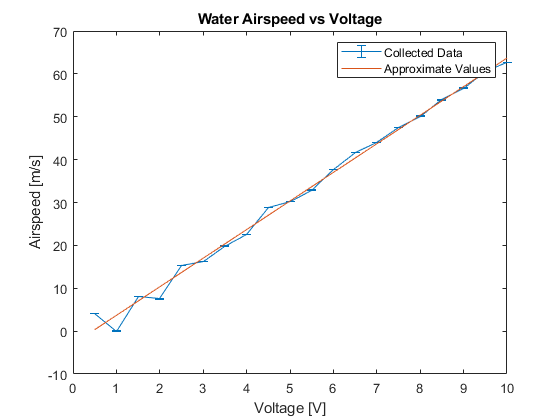


errorbar(finalAvg.Voltage, finalAvg.AirspeedV, EVenturiWater);
hold on;
plot(finalAvg.Voltage, VenturiWater);
hold off;
xlabel('Voltage [V]');
ylabel('Airspeed [m/s]');
title('Water Airspeed vs Voltage');
legend('Collected Data', 'Approximate Values');

## Section 6

## Section 7

## Functions

function out = errorPS(deltaP, R, Tatm, Patm, errorDeltaP, errorPatm, errorTatm)
% Error propagation Pitot-Static Probe Configuration
% Takes in
% Output error in velocity measurement
    partialPS_deltaP = nan;
    partialPS_Patm = nan;
    partialPS_Tatm = nan;
    out = sqrt( (partialPS_deltaP * errorDeltaP)^2 + (partialPS_Patm * errorPatm)^2 + (partialPS_Tatm * errorTatm)^2 );
end

function out = errorVT(deltaP, R, Tatm, Patm, A1, A2, errorDeltaP, errorPatm, errorTatm)
% Error propagation Venturi Tube Configuration
% Takes in
% Output error in velocity measurement
    partialVT_deltaP = nan;
    partialVT_Patm = nan;
    partialVT_Tatm = nan;
    out = sqrt( (partialVT_deltaP * errorDeltaP)^2 + (partialVT_Patm * errorPatm)^2 + (partialVT_Tatm * errorTatm)^2 );
end